clear all;

Calculator of params for help

target_f_BW = 100 *2 * pi;

freq = logspace(0, 5, 10000)*2*pi; 
mag = abs(freqresp(mass_spring_plant, target_f_BW));
P_suggested = 1/(3*mag);
I_suggested = target_f_BW*0.1;
D_suggested = target_f_BW/3;
D_t_suggested = D_suggested * 9;
LPF_suggested = target_f_BW*10;

P_term = logspace(3, 5, 100);
D_term = (logspace(0,4, 100))*2*pi; 
F_term = logspace(0, 5, 100)*2*pi; 

W_term = logspace(1, 3, 100)*2*pi; 
Q_term = logspace(-2, 2, 100)*2*pi; 

params.P   = P_suggested;
params.I   = I_suggested;     
params.D_d = D_suggested;  
params.D_t = D_t_suggested;  
params.LPF = LPF_suggested;
params.w_1 = 225 * 2* pi; %suggested notch freq
params.w_2 = 225 * 2* pi; %suggested notch freq
params.Q_1 = 5;
params.Q_2 = params.Q_1/1000;

Configurations I need to change

params.P = 'X';
params.w_1 = 'Y';
xvar = 'Proportional Filter (P)';
yvar = 'Notch frequency (w_N)';
% Proportional Integrative Derivative
% Proportional Filter (P)
% Integrative Filter (I)
% Derivative Filter (D)
% Low-pass Filter (LPF)
% Notch frequency 1 (w_1)
% Notch frequency 2 (w_2)
% Q-factor 1 (Q_1)
% Q-factor 2 (Q_2)

[X, Y] = meshgrid(P_term, Q_term);
%Z = NaN(size(X)); % Preallocate matrix for 0 dB crossing frequencies
s = tf('s');
%flags = NaN(size(X));
%GMs = NaN(size(X));
%PMs = NaN(size(X));
%MMs = NaN(size(X));

Z_temp = NaN(numel(X), 1); 
f_temp = NaN(numel(X), 1);
%GM_temp = NaN(numel(X), 1);
%PM_temp = NaN(numel(X), 1);
%MM_temp = NaN(numel(X), 1);

numPoints = numel(X);  % Total number of grid points
tic;
% Use parfor on a single loop over all (i, j) pairs
parfor idx = 1:numPoints
    [i, j] = ind2sub(size(X), idx);  % Convert linear index to 2D indices

% Compute objective function values for each (D, I) pair
    localParams = params;
    localParams.P = X(i,j);
    localParams.w_1 = Y(i,j);
    %ratio = Y(i,j);
    %localParams.D_t = localParams.D_d*9;
    localParams.w_2 = localParams.w_1;
    %localParams.Q_1 = localParams.Q_1 * ratio;
    %localParams.Q_2 = localParams.Q_2 * ratio;
    C = localParams.P * ...
        (1 + localParams.I/s) *...
        (((s/localParams.D_d) + 1) / ...
        ((s/(localParams.D_t)) + 1)) * ...
        (1/((s/localParams.LPF) + 1)) * ...
        ((s/localParams.w_1)^2 + ...
        (s/(localParams.w_1 * localParams.Q_1)) + 1) /...
        ((s/localParams.w_2)^2 + ...
        (s/(localParams.w_2 * localParams.Q_2)) + 1);
    margins = allmargin(mass_spring_plant*C);
    GM = margins.GainMargin(1,end);
    PM = margins.PhaseMargin(1,1);
    f_BW = margins.DMFrequency(1,1);
    if (GM <= 6) || (PM <= 40)
        flag = 0;
    else
        flag = 1;
    end
    % Store frequency value in Z-matrix (only if valid)

    Z_temp(idx) = f_BW;
    f_temp(idx) = flag;
    %GM_temp(idx) = GM;
    %PM_temp(idx) =  PM;
    %MM_temp(idx) =  MM;
end
Z = reshape(Z_temp, size(X));
flags = reshape(f_temp, size(X));

toc

Elapsed time is 23.417260 seconds.


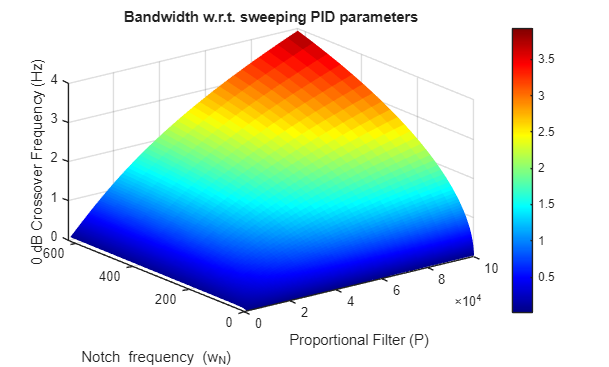

clf;figure;
surf(X, Y, Z, 'EdgeColor', 'none'); % Smooth surface
colorbar;
xlabel(xvar);
ylabel(yvar);
zlabel('0 dB Crossover Frequency (Hz)');
title('Bandwidth w.r.t. sweeping PID parameters');
colormap(jet);

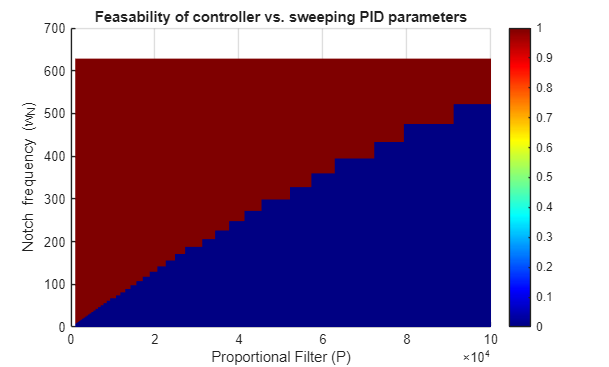

clf;figure;
surf(X, Y, flags, 'EdgeColor', 'none'); % Smooth surface
colorbar;
xlabel(xvar);
ylabel(yvar);
zlabel('0 dB Crossover Frequency (Hz)');
title('Feasability of controller vs. sweeping PID parameters');
colormap(jet);
view(2);  % Set to top-down 2D view
clim([0 1]);

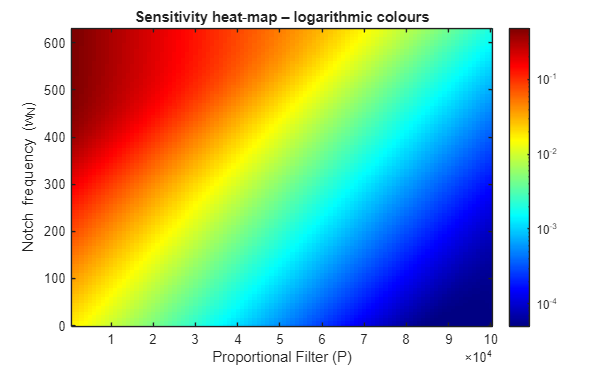

xvec = X(1,:);
yvec = Y(:,1);
[dZdy, dZdx] = gradient(Z, yvec, xvec);
gmag = hypot(dZdx, dZdy);

clf;figure;
imagesc(xvec, yvec, gmag);     % colour = gradient magnitude
axis xy;                        % y‑axis pointing up
set(gca,'ColorScale','log'); 
colormap jet;                   % vivid “hot‑cold” palette
colorbar;
xlabel(xvar);
ylabel(yvar);
title('Sensitivity heat‑map – logarithmic colours');

K_p assumed brute force approach

counter = 0;
f_BW_optimised = 0;
for w_d_idx = 1:D_size
    for w_i = I_term
        for w_f = F_term
            w_d = D_term(w_d_idx);
            C_PID = K_p*(1+(w_i/s))*(((s/w_d) + 1) / (((s/(w_d*3)) + 1)));
            LPF = 1/((s/w_f) + 1);
            C = C_PID * LPF;
            [f_BW ,flag] = cost_function_controller(P, C);
            if (flag==1) && (f_BW_optimised < f_BW)
                f_BW_optimised = f_BW
            end
        end
    end
    counter = counter + 1
end

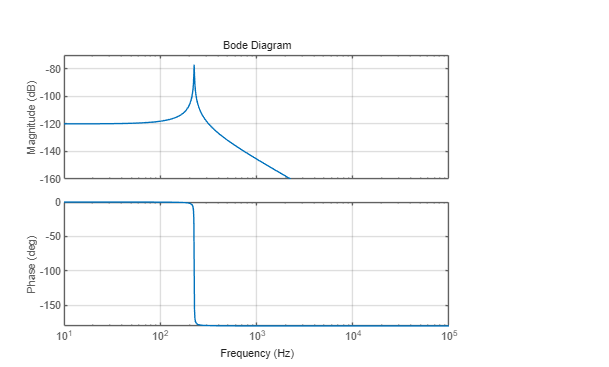

s = tf('s');
m = 0.5;
k = 1e6;
c = 5;
P = 1/(k + c*s + m*s^2);
bode(P,opts)